# Loading the Filter and the Coefficients

% the filter
load Hd;
% the correction coefficients
load beamforming_hw_correction_coeffs.mat;

# Reading one file to get parameters

folder = 'Female Voice 90deg 60dBA Noise 180deg 60dBA';
filename = [folder filesep 'Micro 1_001.wav'];
% reading one audio file
[y, Fs] = audioread(filename)

y =    -0.0002
   -0.0000
    0.0001
    0.0003
    0.0004
    0.0005
    0.0007
    0.0009
    0.0013
    0.0016


Fs = 48000


% size of the Samples
sizeArray = length(y);
% Number of microphones
N_mic = 16;
% zero array of size
% % (nb_Samples, nb_Micros)
sigArray = zeros(sizeArray, N_mic);

# Reading all files

for i = 1:N_mic 
    [y, Fs] = audioread(sprintf([folder '/Micro %d_001.wav'], i));
    sigArray(:, i) = y;
end
sigArray

sigArray =    -0.0002    0.0004   -0.0015   -0.0013   -0.0015   -0.0031   -0.0003    0.0008    0.0001    0.0010    0.0003    0.0003   -0.0002   -0.0011   -0.0022   -0.0002
   -0.0000    0.0004   -0.0014   -0.0009   -0.0021   -0.0030   -0.0003    0.0010    0.0002    0.0012   -0.0003    0.0005   -0.0004   -0.0007   -0.0022   -0.0000
    0.0001    0.0004   -0.0012   -0.0008   -0.0027   -0.0028   -0.0004    0.0010    0.0004    0.0011   -0.0007    0.0008   -0.0005   -0.0003   -0.0022   -0.0000
    0.0003    0.0003   -0.0010   -0.0007   -0.0031   -0.0024   -0.0006    0.0008    0.0005    0.0009   -0.0010    0.0011   -0.0006    0.0002   -0.0022   -0.0002
    0.0004    0.0001   -0.0008   -0.0009   -0.0034   -0.0019   -0.0009    0.0004    0.0006    0.0006   -0.0012    0.0015   -0.0007    0.0005   -0.0022   -0.0005
    0.0005    0.0000   -0.0006   -0.0009   -0.0034   -0.0014   -0.0013    0.0001    0.0006    0.0003   -0.0012    0.0017   -0.0007    0.0008   -0.0021   -0.0009
    0.0007   -0.0001   

# Calculating the Correction Coefficients

Y_ref_rms = rms(y(Fs : end)); % Fs:end to jump first second(transient)
MAT_rms = rms(sigArray(Fs:end, :)); % sigArray(rows, cols)

correct_coeffs = MAT_rms.^(-1).* Y_ref_rms; 
% .* Element-wise multiplication
% .^ Element-wise power

% saving the correction coeffs as CORRECT_COEFFS % IF needed
% save beamforming_hw_correction_coeffs correct_coeffs

# Correcting the Signal

% the entire signal corrected
sigCorrected = zeros(sizeArray, N_mic);

for i = 1:N_mic
    sigCorrected(:, i) = sigArray(:, i) * correct_coeffs(i);
end

# Ploting figures

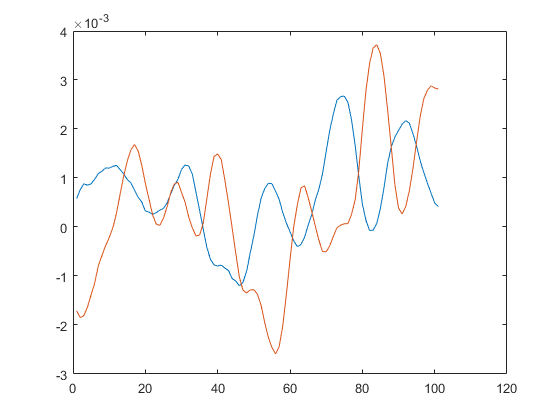

% figure(1)
% plot(y(Fs: Fs+100, :))
figure(2)
plot( sigArray(Fs: Fs+100, 7:8))

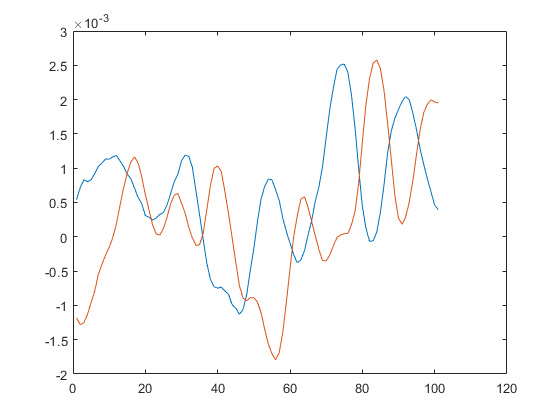

figure(3)
plot( sigCorrected(Fs: Fs+100, 7:8))

# Filtering

filtered = filter(Hd, sigCorrected);
filtered

filtered =    1.0e-04 *

   -0.0015    0.0040   -0.0118   -0.0104   -0.0135   -0.0274   -0.0024    0.0050    0.0009    0.0095    0.0027    0.0027   -0.0019   -0.0109   -0.0213   -0.0018
   -0.0019    0.0082   -0.0237   -0.0186   -0.0334   -0.0564   -0.0055    0.0120    0.0031    0.0215    0.0005    0.0083   -0.0063   -0.0189   -0.0442   -0.0023
   -0.0020    0.0139   -0.0392   -0.0302   -0.0646   -0.0951   -0.0107    0.0214    0.0073    0.0369   -0.0048    0.0186   -0.0132   -0.0272   -0.0765   -0.0036
   -0.0007    0.0202   -0.0577   -0.0447   -0.1088   -0.1423   -0.0187    0.0322    0.0138    0.0554   -0.0147    0.0349   -0.0231   -0.0334   -0.1183   -0.0066
    0.0019    0.0267   -0.0778   -0.0625   -0.1652   -0.1944   -0.0310    0.0433    0.0229    0.0755   -0.0296    0.0586   -0.0361   -0.0367   -0.1685   -0.0122
    0.0067    0.0325   -0.0983   -0.0822   -0.2320   -0.2467   -0.0487    0.0533    0.0341    0.0945   -0.0494    0.0897   -0.0514   -0.0348   -0.2234   -0.0225
    0.014

# Sum up and Writedown the Filtered and corrected audio file

% result = zeros(N_mic, 1);

for i=1:sizeArray
    result(i) = sum(filtered(i, :));
end

audiowrite('./CorrFil_all.wav', 200 * result, Fs)

# Doing beamforming

% required to shifted the audio data according to the delay and the
% microphone distance
% these formulas were taken from the internet,
% despite they are on the Audio acquisition lecture; from slide 10 and on!
% still need to check if it is correct!
delay= zeros(1, N_mic);
filtered_z = filtered;

phi = pi/2;
d = 0.07;
c = 340;

for i=1:16
    delay(1,i)= d*i*cos(phi)/c;
end

shifted_z = zeros(sizeArray, N_mic);

for i=1:8
    shifted_z(:,i) = delayseq(filtered_z(:,i), -delay(1,8)/2 + (i-8)*delay(1,i));
end

for i=9:16
    shifted_z(:, i) = delayseq(filtered_z(:,i), +delay(1,9)/2 + (i-9)*delay(1,i));
end
shifted_z

shifted_z =    1.0e-04 *

   -0.0015    0.0040   -0.0118   -0.0104   -0.0135   -0.0274   -0.0024    0.0050    0.0009    0.0095    0.0027    0.0027   -0.0019   -0.0109   -0.0213   -0.0018
   -0.0019    0.0082   -0.0237   -0.0186   -0.0334   -0.0564   -0.0055    0.0120    0.0031    0.0215    0.0005    0.0083   -0.0063   -0.0189   -0.0442   -0.0023
   -0.0020    0.0139   -0.0392   -0.0302   -0.0646   -0.0951   -0.0107    0.0214    0.0073    0.0369   -0.0048    0.0186   -0.0132   -0.0272   -0.0765   -0.0036
   -0.0007    0.0202   -0.0577   -0.0447   -0.1088   -0.1423   -0.0187    0.0322    0.0138    0.0554   -0.0147    0.0349   -0.0231   -0.0334   -0.1183   -0.0066
    0.0019    0.0267   -0.0778   -0.0625   -0.1652   -0.1944   -0.0310    0.0433    0.0229    0.0755   -0.0296    0.0586   -0.0361   -0.0367   -0.1685   -0.0122
    0.0067    0.0325   -0.0983   -0.0822   -0.2320   -0.2467   -0.0487    0.0533    0.0341    0.0945   -0.0494    0.0897   -0.0514   -0.0348   -0.2234   -0.0225
    0.01

mic = phased.OmnidirectionalMicrophoneElement('FrequencyRange',[20 20e3])

mic =   phased.OmnidirectionalMicrophoneElement with properties:

    FrequencyRange: [20 20000]
       BackBaffled: false



arr_microphones = phased.ULA('NumElements', 16, 'ElementSpacing', 0.07, 'ArrayAxis','x',...
    'Element', mic)

arr_microphones =   phased.ULA with properties:

           Element: [1×1 phased.OmnidirectionalMicrophoneElement]
       NumElements: 16
    ElementSpacing: 0.0700
         ArrayAxis: 'x'
             Taper: 1



ang = [90; 0];   % 1st for azimuth, 2nd for elevation *in degrees..
                    
c = 340;

beamformer = phased.TimeDelayBeamformer('SensorArray', arr_microphones,...
    'SampleRate', Fs,'PropagationSpeed',c,...
    'Direction', ang);

out_audio = beamformer(shifted_z)

out_audio =    1.0e-05 *

   -0.0488
   -0.0984
   -0.1682
   -0.2578
   -0.3656
   -0.4865
   -0.6126
   -0.7334
   -0.8375
   -0.9133


# Plot between the Corrected-Filtered[micro=14] and the Beamformed Signal

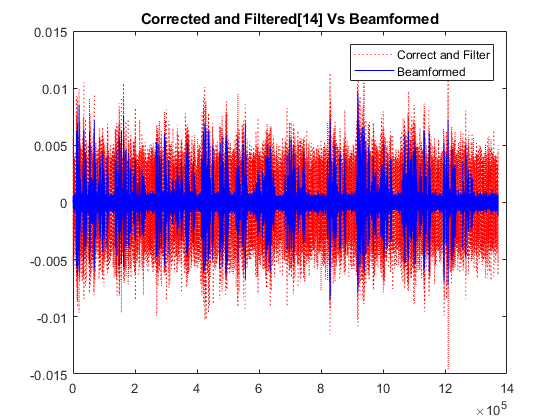

plot(filtered(:, 14), 'r:')
hold on
title('Corrected - Filtered[14] Vs Beamformed')
plot(out_audio, 'b')
legend('Correct and Filter', 'Beamformed')

audiowrite('./Beamformed_90_dgr.wav', 200 * out_audio, Fs)

# Directivity plot

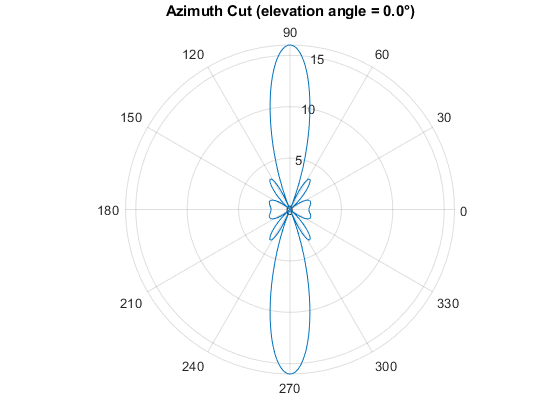

figure(5)
directivity_plot(16, 0.07, 800, 90, 340) % nb_Mics; distance between mics; Hz; angle_direction; sound speed at m/s